# K_PSTHCorr_demo.mlx

Written by Kouichi C. Nakamura Ph.D.

MRC Brain Network Dynamics Unit

University of Oxford

kouichi.c.nakamura@gmail.com

17-Nov-2016 17:51:40

See also

`K_PSTHCorr`

`K_PSTHCorr_test`

clear;close all;clc

% startdir = fileparts(which('startup'));
% endind = regexp(startdir,regexptranslate('escape',...
%     'Private_Dropbox'),'end');
% if ~isempty(endind)
%     basedir = startdir(1:endind); % platform independent
%     clear endind startdir
% else
%     error('move to the folder "%s"',fullfile('Kouichi MATLAB data','thalamus'))
% end
% 
% datafile = fullfile(basedir,'Kouichi MATLAB data',...
%     'thalamus','S potentials','HF pauser','PC','SWA',...
%     'kjx021i01_i02_spliced.mat');

url = 'https://unioxfordnexus-my.sharepoint.com/:u:/g/personal/phar0528_ox_ac_uk/EaSoDxyB_n9PvlWYyZxRWjsBwB8zOmNvepI_qz-TBXMV3A?e=pZDBvz'

url = 'https://unioxfordnexus-my.sharepoint.com/:u:/g/personal/phar0528_ox_ac_uk/EaSoDxyB_n9PvlWYyZxRWjsBwB8zOmNvepI_qz-TBXMV3A?e=pZDBvz'

web(url,'-browser') % Download this file

[datafile_,path] = uigetfile('*\kjx021i01_i02_spliced.mat','Choose kjx021i01_i02_spliced.mat');
% 330MB

datafile =fullfile(path,datafile_);
clear datafile_



## PSTH (peri-stimulus time histogram)

psth, target smalle, trigger onset
The number of sweeps 35


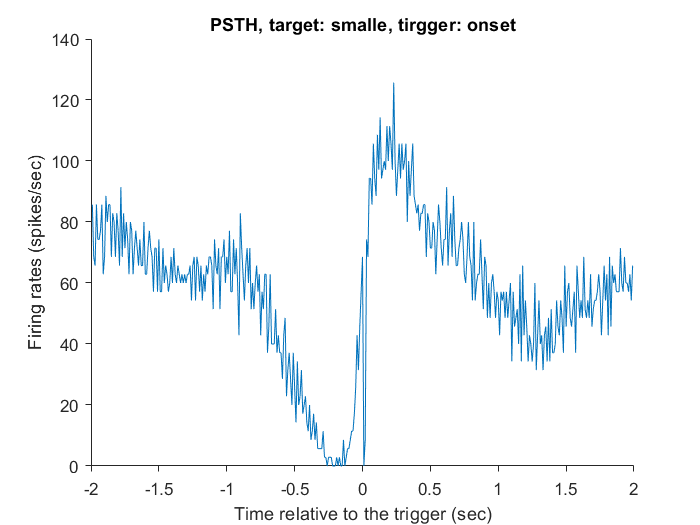



load(datafile);

sInterval = smalle.interval;

target = smalle.values(1:round(200/sInterval)); % 200 sec

trigger = onset.values(1:round(200/sInterval));

width = 4;% sec
offset = 2; %sec

mode = 'psth';
binsize = 0.010;

tic
[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode, 'targettitle' , 'smalle', ...
    'TriggerTitle' , 'onset', 'histY', 'rate');

toc

Elapsed time is 0.359337 seconds.


psth, target , trigger 
The number of sweeps 35


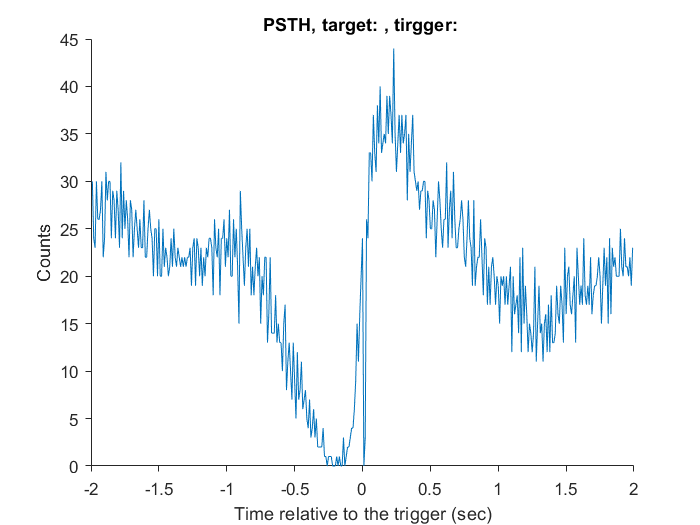

mode = 'psth';
binsize = 0.010;


[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'HistY', 'count');

psth, target smalle, trigger onset
The number of sweeps 35


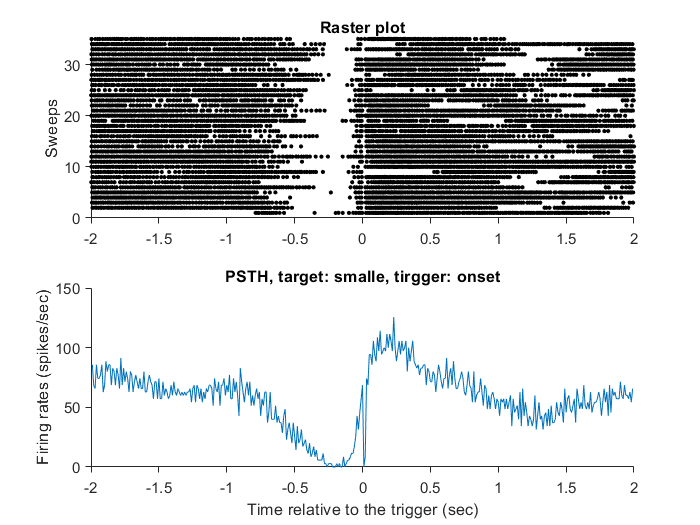


[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate', 'Unit', 's', 'Raster', 'on','RasterType','dot');

psth, target smalle, trigger onset
The number of sweeps 35


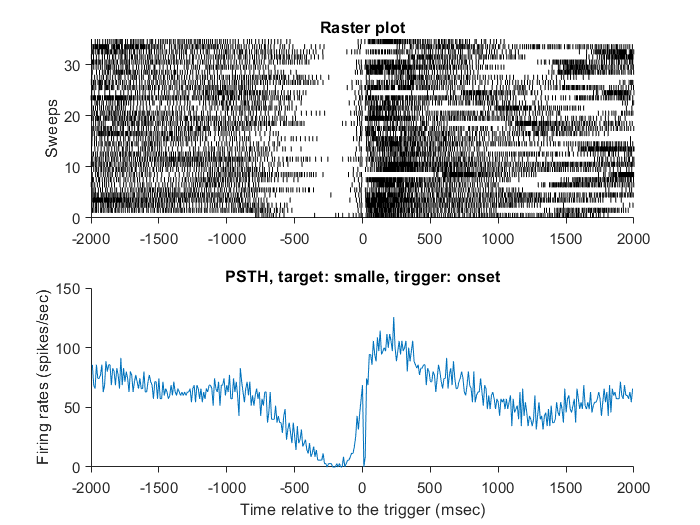


[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate', 'Unit', 'ms', 'Raster', 'on','RasterType','line');

psth, target smalle, trigger onset
The number of sweeps 35


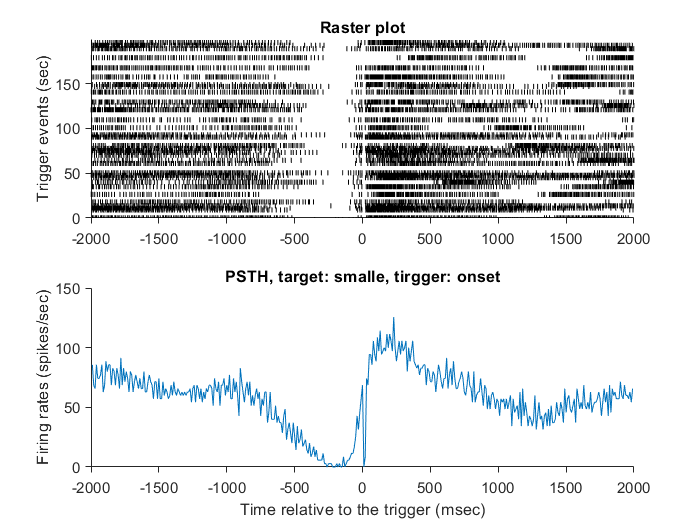

[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate', 'Unit', 'ms', 'Raster', 'on','RasterType','line','RasterY', 'time');

psth, target smalle, trigger onset
The number of sweeps 35


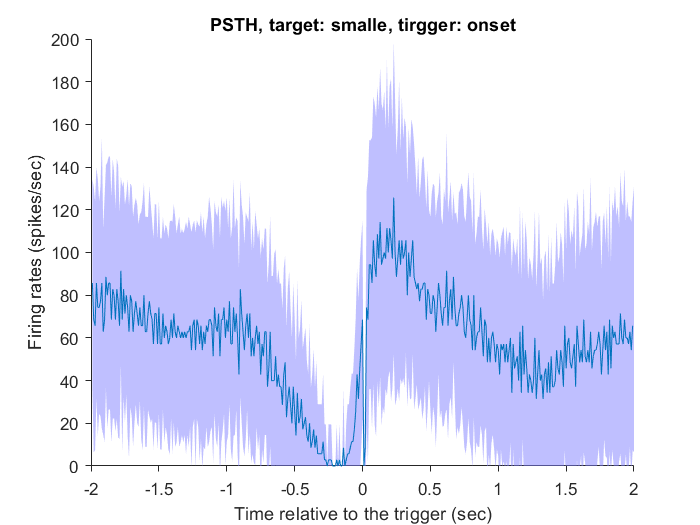


[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate',  'ErrorBar', 'std');

psth, target smalle, trigger onset
The number of sweeps 35


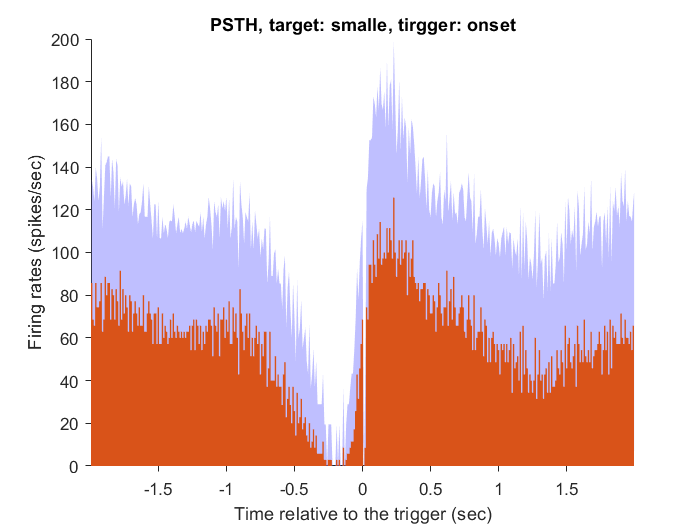


[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate',  'ErrorBar', 'std','PlotType','hist');

## Correlograms



width = 4;% sec
binsize = 0.010;
offset = 2; %sec



## Crosscorrelogram

crosscorr, target smalle, trigger onset
The number of sweeps 107


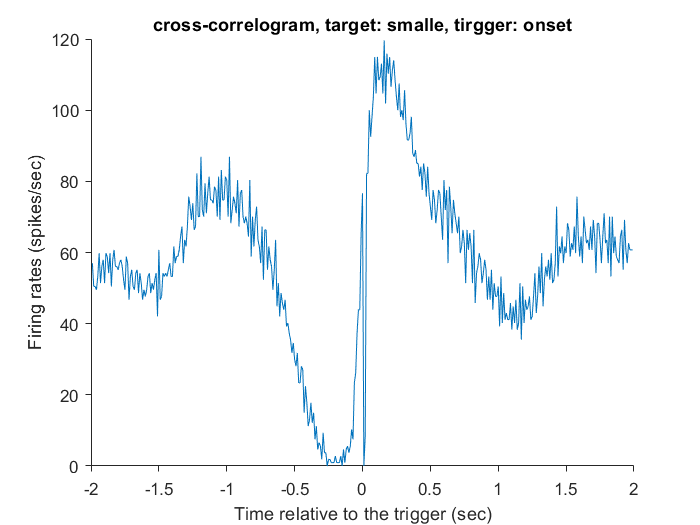

mode = 'crosscorr';

[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate');

crosscorr, target , trigger 
The number of sweeps 107


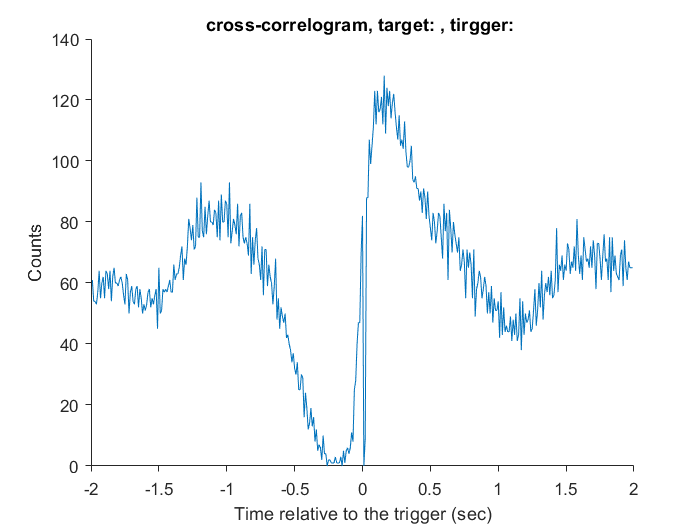


[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'HistY', 'count');

crosscorr, target smalle, trigger onset
The number of sweeps 107


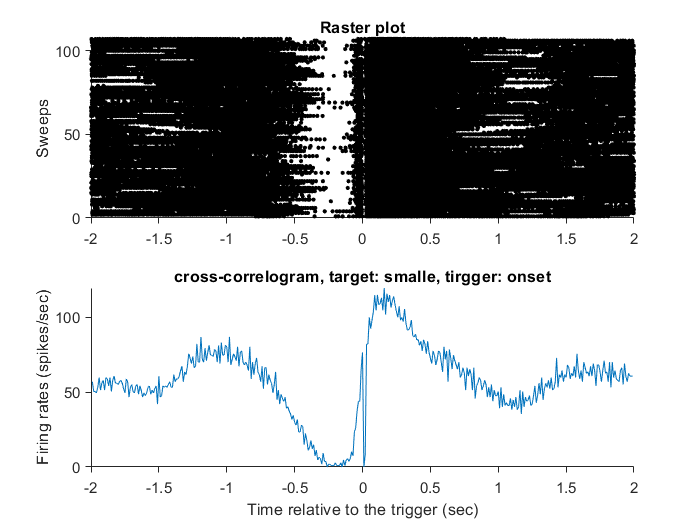


[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset,'Mode',mode, 'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate', 'Unit', 's', 'Raster','on','RasterType', 'dot');

crosscorr, target smalle, trigger onset
The number of sweeps 107


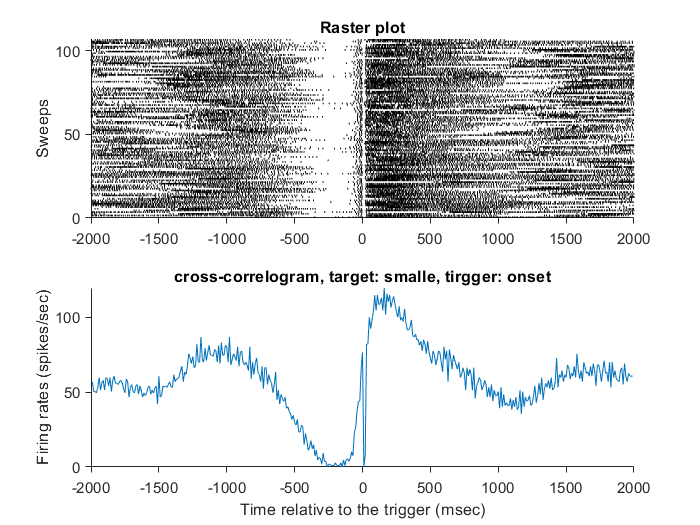

[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate', 'Unit', 'ms', 'Raster','on','RasterType','line');

crosscorr, target smalle, trigger onset
The number of sweeps 107


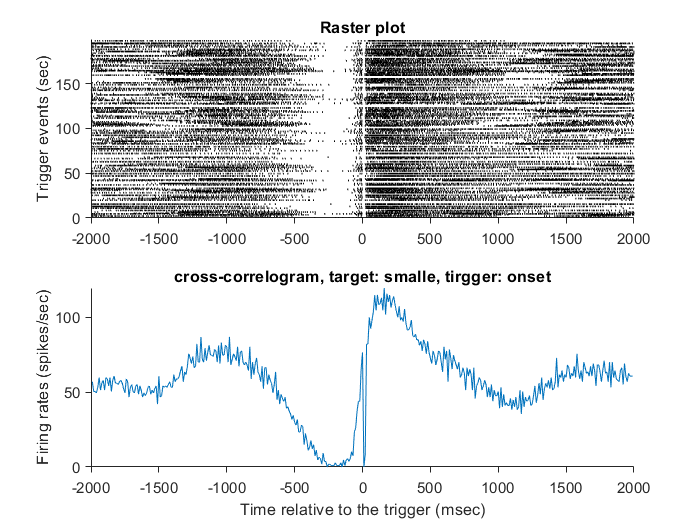

[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate', 'Unit', 'ms', 'Raster', 'on','RasterType','line','RasterY', 'time');

crosscorr, target smalle, trigger onset
The number of sweeps 107


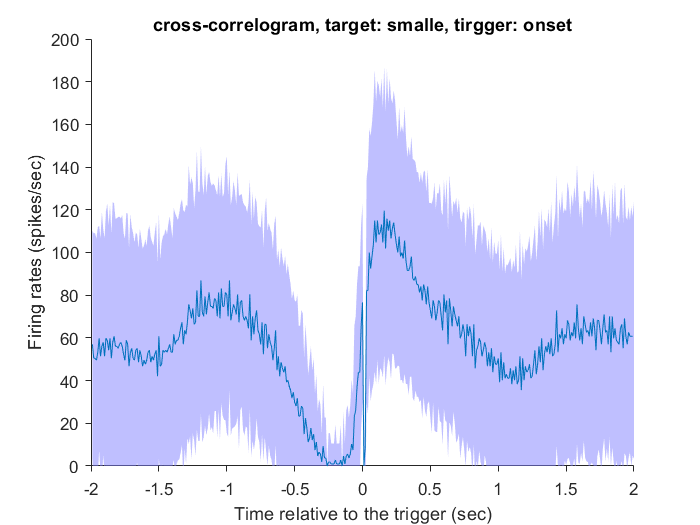

[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate',  'ErrorBar', 'std');

crosscorr, target smalle, trigger onset
The number of sweeps 107


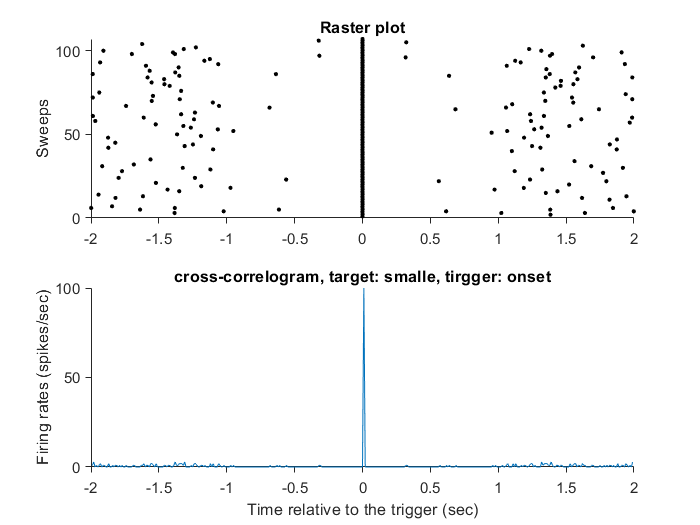

mode = 'crosscorr';
binsize = 0.010;

[out1] = K_PSTHcorr(trigger, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate', 'Raster','on','RasterType', 'dot');

## Autocorrelogram

autocorr, target smalle, trigger onset
The number of sweeps 107


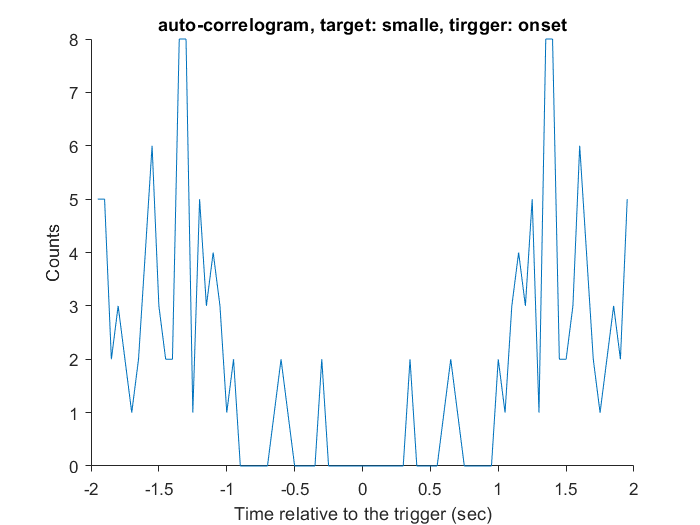

mode = 'autocorr';

binsize = 0.050;
[out1] = K_PSTHcorr(trigger, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset'); %TODO no title

autocorr, target smalle, trigger onset
The number of sweeps 107


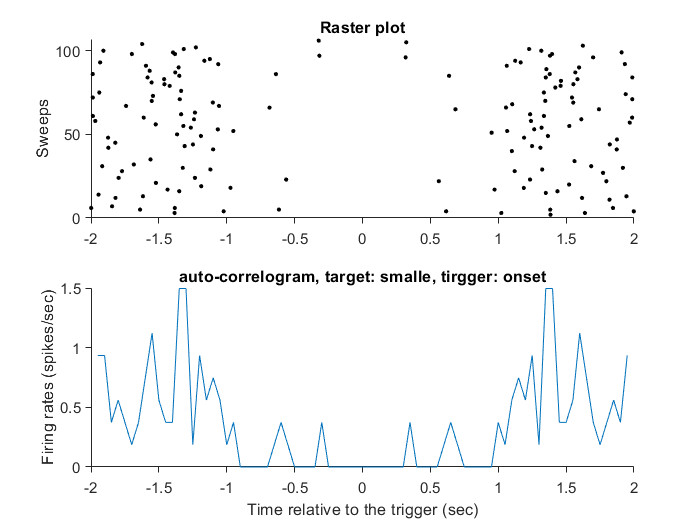


[out1] = K_PSTHcorr(trigger, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate', 'Raster','on','RasterType', 'dot');

autocorr, target smalle, trigger onset
The number of sweeps 11807


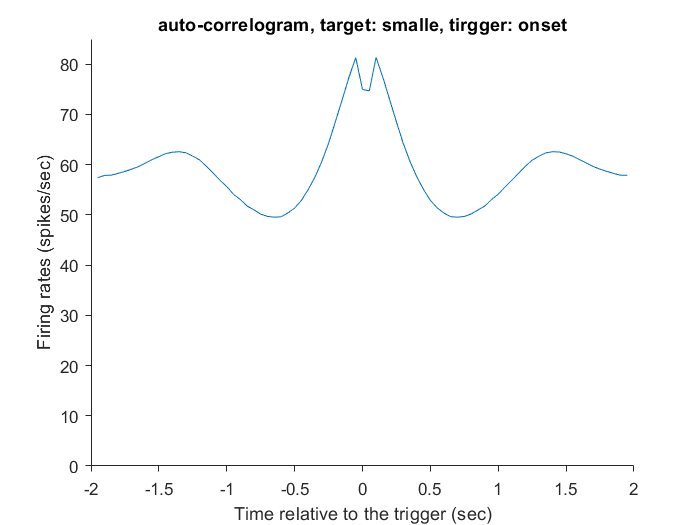


[out1] = K_PSTHcorr(target, target, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate'); %TODO no title

## SDF (spike density funciton)



width = 4;% sec
binsize = 0.010;
offset = 2; %sec


psth, target , trigger 
The number of sweeps 35


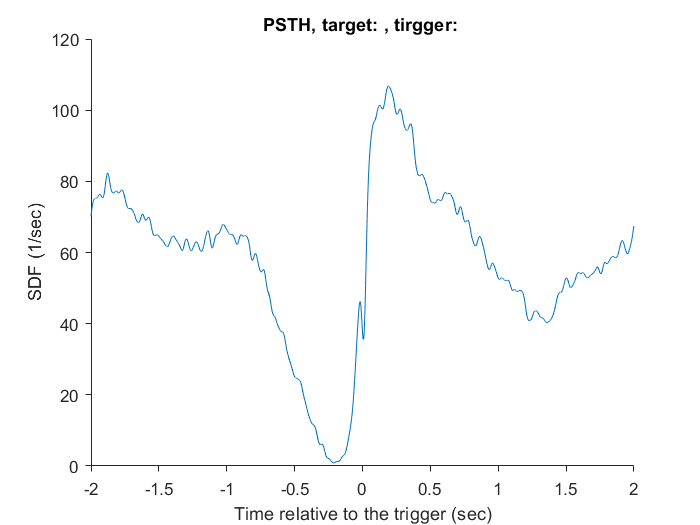


mode = 'psth';
binsize = 0.001;

[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'SDF','on','SDFsigma', 'default');

psth, target , trigger 
The number of sweeps 35


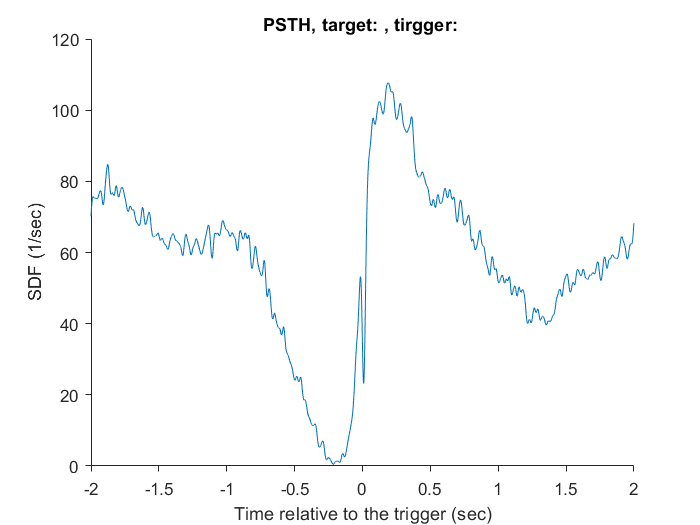


[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'SDF','on','SDFsigma', 0.01);

psth, target , trigger 
The number of sweeps 35


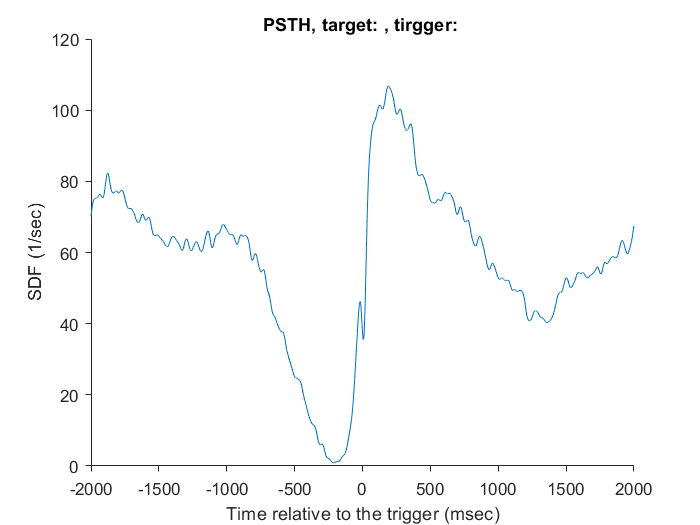


[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset,'Mode',mode, 'SDF', 'on','SDFsigma','default', 'Unit', 'ms');

psth, target smalle, trigger onset
The number of sweeps 35


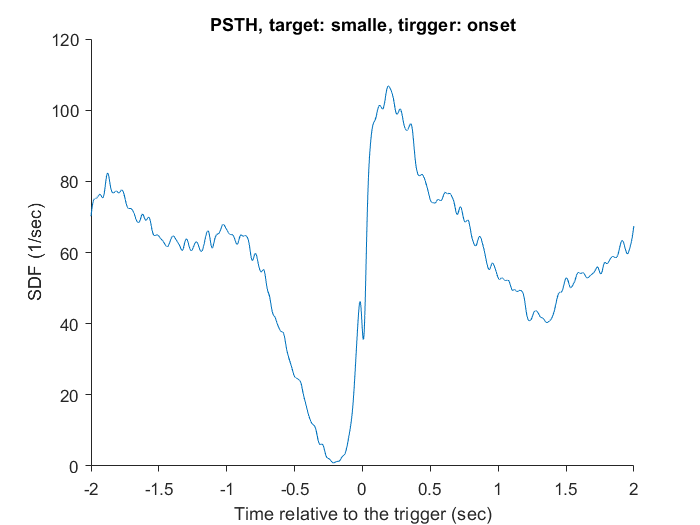


[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate', 'Unit', 's', 'SDF', 'on','SDFsigma','default');

psth, target smalle, trigger onset
The number of sweeps 35


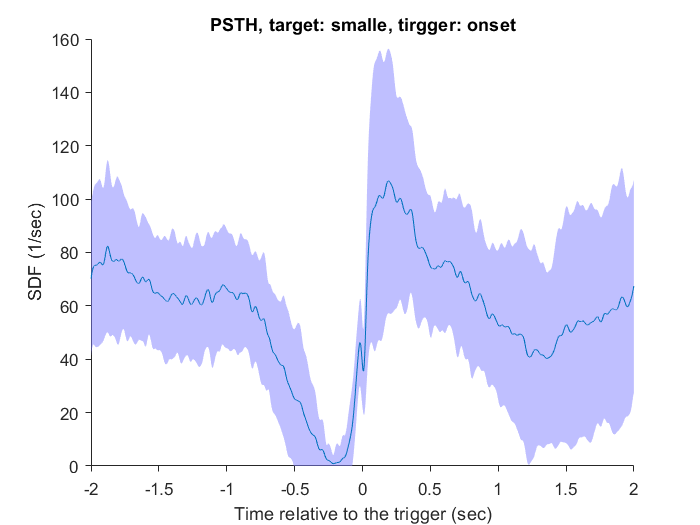


[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate',  'ErrorBar', 'std', 'SDF', 'on','SDFsigma','default');

psth, target smalle, trigger onset
The number of sweeps 35


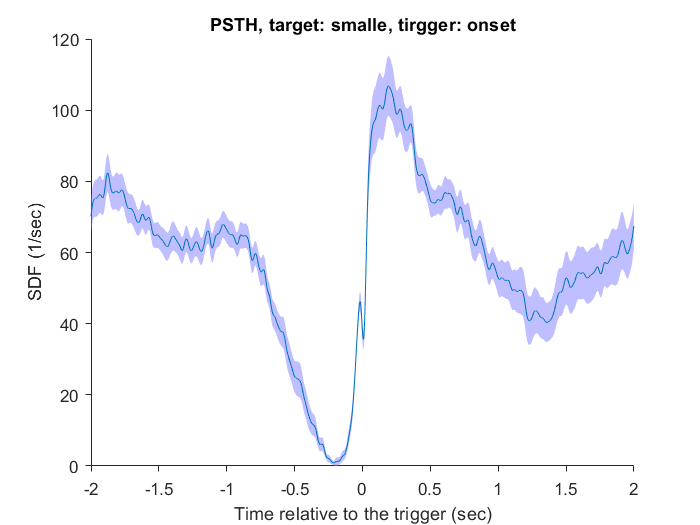


[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate',  'ErrorBar', 'sem', 'SDF','on','SDFsigma', 'default');

psth, target smalle, trigger onset
The number of sweeps 35


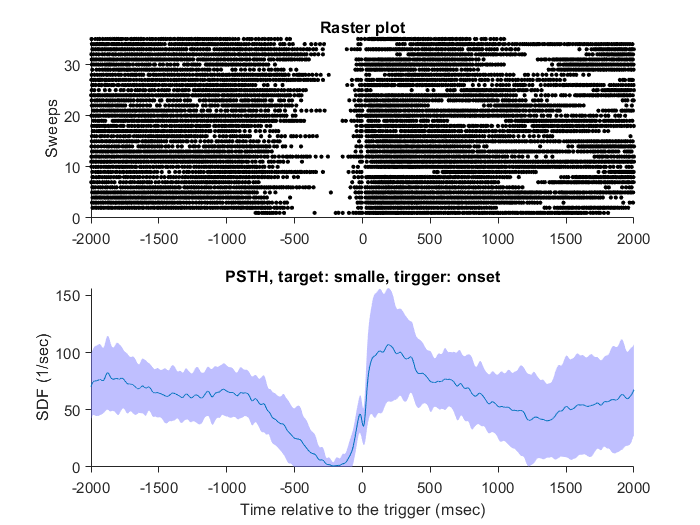


[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate',  'ErrorBar', 'std', 'SDF', 'on','SDFsigma','default', 'Raster', 'on','RasterType','dot', 'Unit', 'ms');

psth, target smalle, trigger onset
The number of sweeps 35


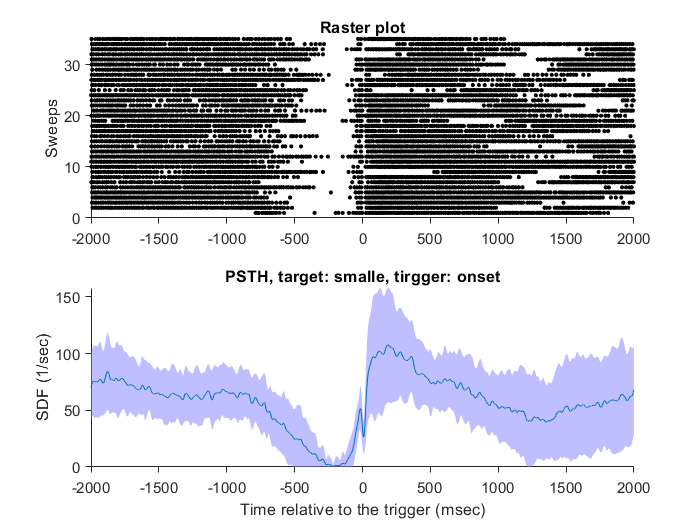


[out1] = K_PSTHcorr(target, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate',  'ErrorBar', 'std', 'SDF','on','SDFsigma', 0.011, 'Raster', 'on','RasterType','dot', 'Unit', 'ms');

## SDF for autocorr

autocorr, target smalle, trigger onset
The number of sweeps 107


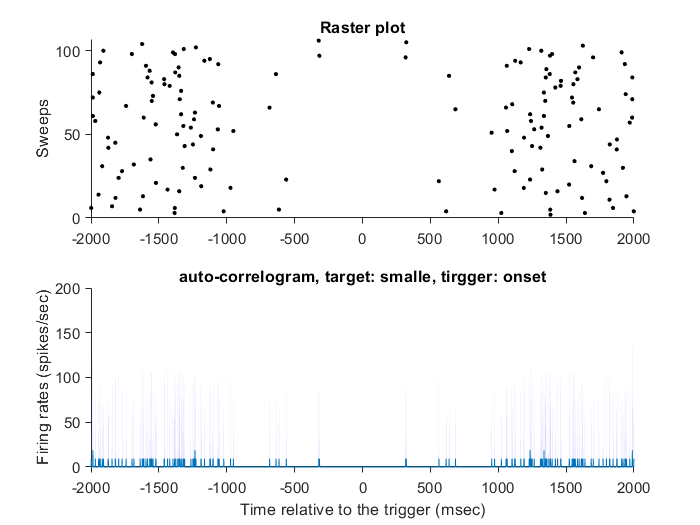


mode = 'autocorr';
binsize = 0.001;
[out1] = K_PSTHcorr(trigger, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate',  'ErrorBar', 'std', 'Raster', 'on','RasterType','dot', 'Unit', 'ms');

autocorr, target smalle, trigger onset
The number of sweeps 107


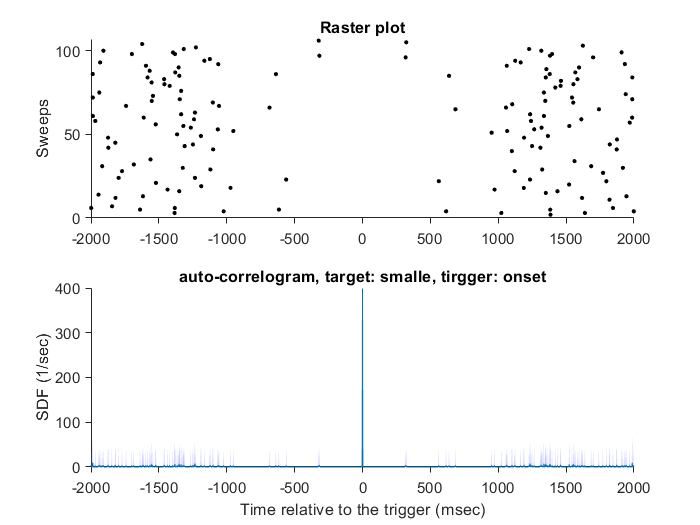


mode = 'autocorr';
binsize = 0.001;
[out1] = K_PSTHcorr(trigger, trigger, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate',  'ErrorBar', 'std', 'SDF','on','SDFsigma', 0.001, 'Raster', 'on','RasterType','dot', 'Unit', 'ms');

## tset SDF for single sweep

Looks like the peak height of single spike is `binsize/sigma*0.4`

But I don't know why.

Maybe, the peak height should be dependent on sigma, i.e. a narrow curve has a large peak, whereas a wide curve has a smaller peak.

But it should not depend on bin size.However you sample it, the height should be the same.

mode = 'psth';

trigger_  = zeros(size(trigger));
trigger_( find(trigger, 1, 'first')) = 1; % just one trial of trigger

binsize = 0.0001;

[out, h] = K_PSTHcorr(target, trigger_, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate',  'ErrorBar', 'sem', 'SDF','on','SDFsigma', 0.001, 'Raster',  'on','RasterType','dot', 'Unit', 'ms');

psth, target smalle, trigger onset
The number of sweeps 1


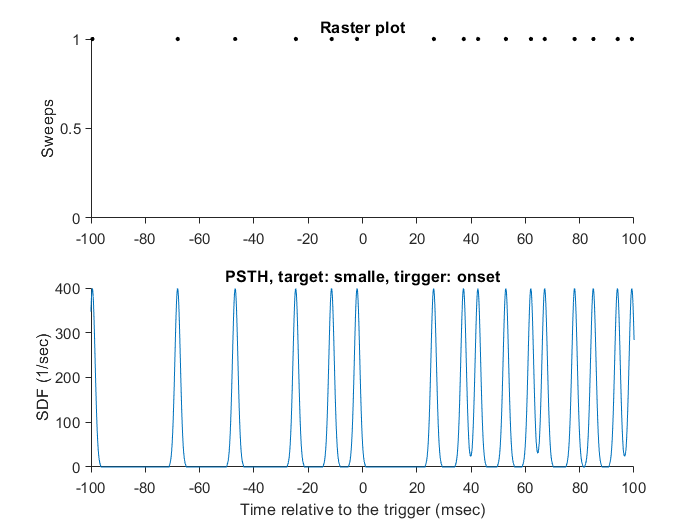


% peak is 0.04 (1/sec)

h.ax1.XLim = [-100 100];




binsize = 0.0005;

[~, h] = K_PSTHcorr(target, trigger_, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate',  'ErrorBar', 'sem', 'SDF', 'on','SDFsigma',0.001, 'Raster',  'on','RasterType','dot', 'Unit', 'ms');

psth, target smalle, trigger onset
The number of sweeps 1


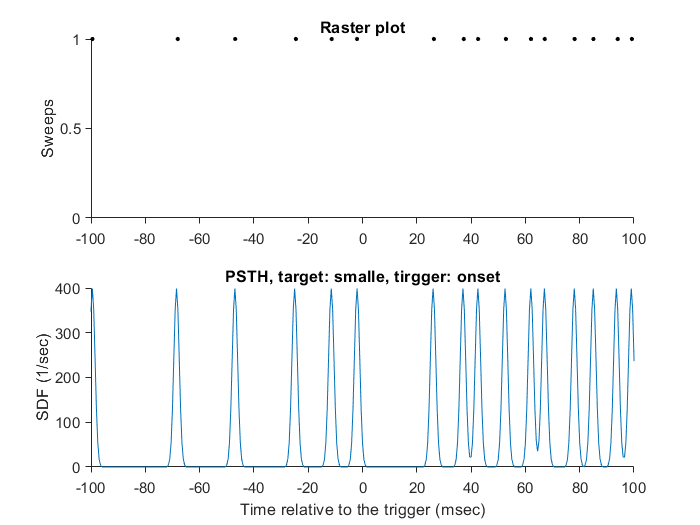


h.ax1.XLim = [-100 100];


% peak is 0.2 (1/sec) ... 5 times bigger than the above


binsize = 0.001;

[~, h] = K_PSTHcorr(target, trigger_, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate',  'ErrorBar', 'sem', 'SDF','on','SDFsigma', 0.001, 'Raster',  'on','RasterType','dot', 'Unit', 'ms');

psth, target smalle, trigger onset
The number of sweeps 1


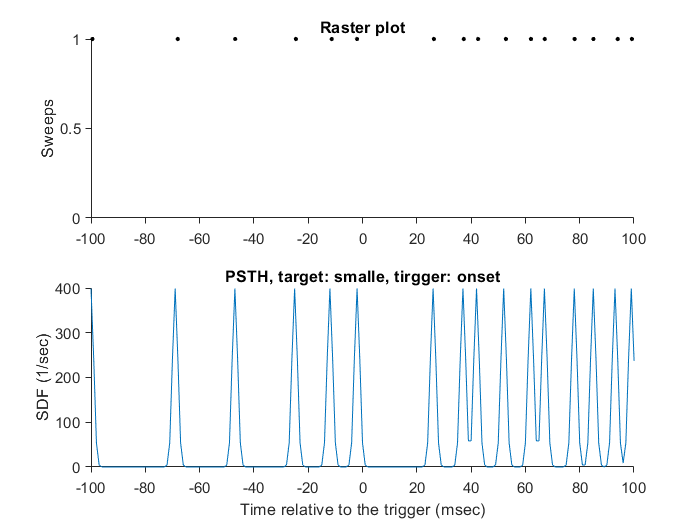


h.ax1.XLim = [-100 100];


% peak is 0.4 (1/sec) ... 10 times bigger than the above


binsize = 0.0001;

[out, h] = K_PSTHcorr(target, trigger_, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate',  'ErrorBar', 'sem', 'SDF','on','SDFsigma', 0.002, 'Raster',  'on','RasterType','dot', 'Unit', 'ms');

psth, target smalle, trigger onset
The number of sweeps 1


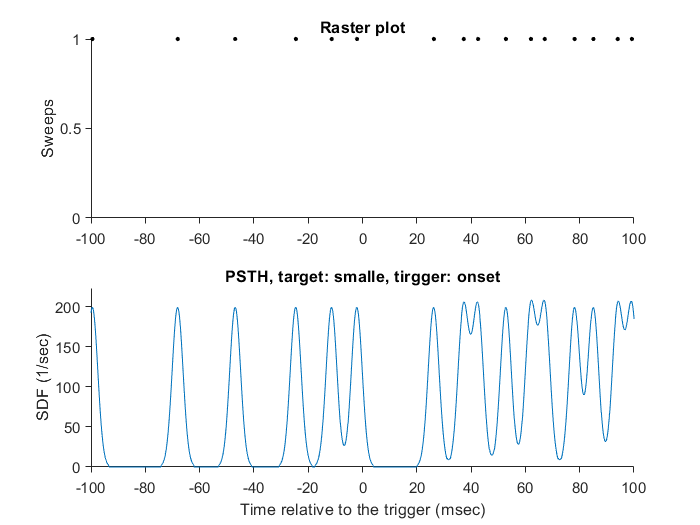


h.ax1.XLim = [-100 100];


% peak is 0.02 (1/sec) ... half of the above

binsize = 0.0001;

[out, h] = K_PSTHcorr(target, trigger_, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate',  'ErrorBar', 'sem', 'SDF', 'on','SDFsigma',0.002, 'Raster', 'on','RasterType', 'dot', 'Unit', 'ms');

psth, target smalle, trigger onset
The number of sweeps 1



h.ax1.XLim = [-100 100];


% peak is 0.02 (1/sec) ... half of the above


binsize = 0.0001;

[out, h] = K_PSTHcorr(target, trigger_, sInterval,...
    width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
    'HistY', 'rate',  'ErrorBar', 'sem', 'SDF','on','SDFsigma', 0.5, 'Raster',  'on','RasterType','dot', 'Unit', 'ms');

psth, target smalle, trigger onset
The number of sweeps 1


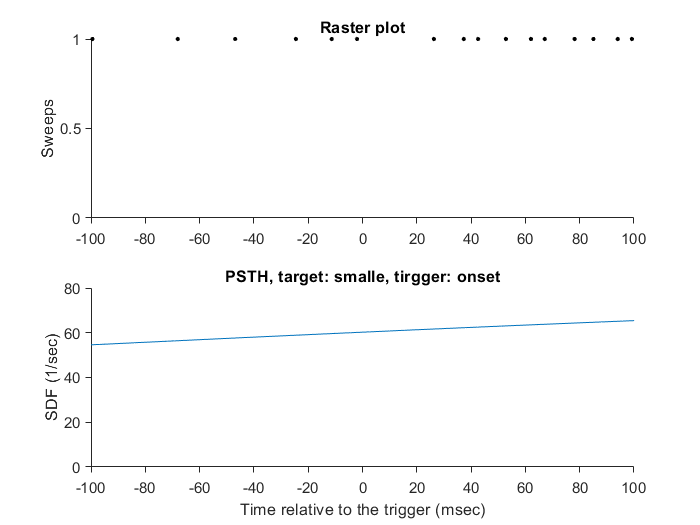


h.ax1.XLim = [-100 100];

## test if an error happens

% mode = 'psth';
% 
% binsize = 0.001;
% clc;profile on
% % sigma = linspace( 0.0001, 0.05, 100);
% sigma = rand(100,1) * 0.05;
% 
% dbstop if error
% 
% for i = 1:100
%     
%     K_PSTHcorr(target, trigger, sInterval,...
%         width, binsize, offset, 'Mode',mode,'targettitle' , 'smalle', 'TriggerTitle' , 'onset',...
%         'HistY', 'rate',  'ErrorBar', 'std', 'SDF', sigma(i), 'Unit', 'ms'); %TODO x axis doesn:t match
%     close
%     
% end

psth, target smalle, trigger onset
The number of sweeps 35


psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35


psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35


psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 

psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35


psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35


psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35


psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35


psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35


psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35


psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35


psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 

psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35


psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35
psth, target smalle, trigger onset
The number of sweeps 35


profile viewer




